# RLC Circuits

- *Electric Circuits Virtual Labs *

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

## Introduction

A circuit with two energy storage elements (a inductor and a capacitor) can be analyzed  by solving second-order differential equations without and with the input signals. If there is no input signal, the response of the circuit is called the zero input response,  source free response, natural response, or transient response.  If there are inputs, the solution of the differential equation is the sum of the complementary solution and the particular solution. Depending on the coefficients, the complementary solution can be overdamped, critically damped, or underdamped.  The form of the particular solution is similar to the input. 

The natural response and step response of circuits containing both inductors and capacitors is form of  two simple structures: the series  RLC circuit and the parallel RLC circuit.

## Learning Objectives

- Be able to determine the natural response and the step response of serial  RLC circuits.

- Be able to plot the natural response and the step response of serial  RLC circuits.

- Be able to determine the natural response and the step response of parallel  RLC circuits.

- Be able to plot  the natural response and the step response of parallel  RLC circuits.

### **Introduction**

The second-order differential equations with constant coefficients and constant input

                 $\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + a_1 \frac { d v ( t ) } { d t } + a_0 v ( t ) = b_0$                                           (1)

The solution to Equation (1) is the sum of the complementary solution vc(t) and the particular solution vp(t)

The complementary solution is the solution to homogeneous differential equation given by

               $\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + a_1 \frac { d v ( t ) } { d t } + a_0 v ( t ) = 0$                                               (2)

Depending on the coefficients, there are three cases - overdamped, critically damped, and underdamped.  The coefficients of the complementary solution are found by applying the initial conditions to sum vc(t) + vp(t) after finding the particular solution

The particular solution is the solution to the original differential equation given by Equation (1), including the input. The form of the particular solution is similar to the input signal. For the constant input, the particular solution will be a constant. Let the particular solution be

                 $v_p(t)=K$                                                                             (3)

Substituting this proposed solution to Equation (1), we obtain

                   $\frac { d ^ { 2 } K } { d t ^ { 2 } } + a_1 \frac { d K } { d t } + a_0 K =b_0$                                                     (4)

Since K is a constant,$\frac{dK}{dt}=0$  and  $\frac{d^2K}{dt^2}=0$ , and Equation (4) becomes $a_0K=b_0$. Thus, for constant input signal, the particular solution to Equation (1) is given by

                $v _ { p } ( t ) = K = \frac { b _ { 0 } } { a _ { 0 } }$                                                                        (5)

## Step response of Serial RLC Circuit  

A series RLC circuit with constant independent Voltage source is given in the following circuit.  The switch in the circuit shown is closed at time t = 0. The initial voltage on the capacitor,$V_0$, represents the initial energy stored in the capacitor at $t=0$. The initial current through the inductor, $I_0$, represents the initial energy stored in the inductor at $t=0$.

            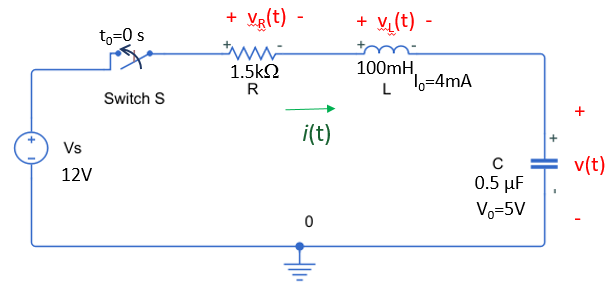

Finding the step  response of a series RLC circuit consists of finding the voltage cross the capacitor  in the series-connected elements by the release of initially stored energy in the inductor, capacitor, or both and input. Then, the current through the capacitor can be determined. If any of the other element voltages are of interest, you can find them after determining the current.

  Sum the voltage drops around the mesh (KVL):

             
$$- V _ { s } + R i ( t ) + L \frac { d i ( t ) } { d t } + v ( t ) = 0$$
                             

 The current through capacitor is given by

            
$$i ( t ) = C \frac { d v ( t ) } { d t }$$
                                                     

 Substitute it  into previous equation

            $- V _ { s } + R C \frac { d v ( t ) } { d t } + L C \frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + v ( t ) = 0$) 

Second order differential equation will be 

           
$$\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + \frac { R } { L } \frac { d v ( t ) } { d t } + \frac { 1 } { L C } v ( t ) = \frac { 1 } { L C } V _ { s }$$


Given values in the circuit

% Given Values
R = 1500       %Resistance ohms

R = 1500

L = 50*10^-3 % Inductor mH

L = 0.0500

C = 0.1*10^-6 %Capacitor uH

C = 1.0000e-07

V0 = 5;          % Initial voltage on the capacitor
I0 = 6e-3;       % Initial current through the inductor
Vs=10;           % Independent Voltage source

 Let's have 

            $a_1=\frac{R}{L},a_0=\frac{1}{LC}, $ and $b_0=\frac{V_s}{LC}$

a1 =R/L; a0 = 1/(L*C); b0 = Vs/(L*C);

Then, differential equation will be 

             
$$\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + a_1\frac { d v ( t ) } { d t } + a_0 v ( t ) = b_0$$


Initial Values are

            
$$v ( 0 ) = V _ { 0 }$$
                                                                 

            
$$ \frac { d v ( 0 ) } { d t } = \frac { i ( 0 ) } { C } = \frac { I _ { 0 } } { C }$$
                                                     

Finding the solution of the differential equation in MATLAB

syms v(t) t i(t) vR(t)

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}v\left(t\right)+30000\,\frac{\partial }{\partial t}v\left(t\right)+200000000\,v\left(t\right)=2000000000$$

eq = diff(v,t,2) + a1*diff(v,t)+a0*v ==  b0 

$$Dv(t) = \frac{\partial }{\partial t}v\left(t\right)$$

Dv = diff(v,t)

$$cond = \left(\begin{array}{cc} v\left(0\right)=5 & \left({\left(\frac{\partial }{\partial t}v\left(t\right)\right)|}_{t=0}\right)=60000 \end{array}\right)$$

cond = [v(0) == 5, Dv(0)== I0/C]

$$v(t) = 10-{\mathrm{e}}^{-20000\,t}-4\,{\mathrm{e}}^{-10000\,t}$$

v(t) = dsolve(eq, cond)

$$v(t) = 10-{\mathrm{e}}^{-20000\,t}-4\,{\mathrm{e}}^{-10000\,t}$$

v(t) = simplify(v(t))

Plotting  the voltage cross the capacitor  v(t)

fplot(v(t),[0.0 0.001],'r' )
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)')

The current through the capacitor is given

            
$$i(t)=C \frac{dv(t)}{dt}$$


i(t) = C*diff(v(t))

$$i(t) = \frac{{\mathrm{e}}^{-10000\,t}}{250}+\frac{{\mathrm{e}}^{-20000\,t}}{500}$$

i(t) = vpa(i(t))

$$i(t) = 0.004\,{\mathrm{e}}^{-10000.0\,t}+0.002\,{\mathrm{e}}^{-20000.0\,t}$$

The voltage across the resistor is given by

            
$$v_R(t)=Ri(t)$$


vR(t) = R*i(t)          % The voltage across the resistor

$$vR(t) = 6.0\,{\mathrm{e}}^{-10000.0\,t}+3.0\,{\mathrm{e}}^{-20000.0\,t}$$

hold on 
fplot(vR(t),[0.0 0.001],'m' )  % Ploting voltage across the resistor over v(t)

The voltage across the inductor is

            
$$v_L(t)=L \frac{di(t)}{dt}$$


vL(t) = L*diff(i(t))        % The voltage across the inductor

$$vL(t) = -2.0\,{\mathrm{e}}^{-10000.0\,t}-2.0\,{\mathrm{e}}^{-20000.0\,t}$$

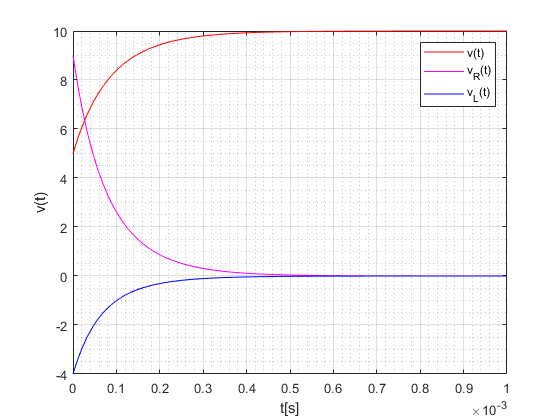

fplot(vL(t),[0.0 0.001],'b' )       % Ploting voltage across the inductor over v(t)
legend ('v(t)', 'v_R(t)', 'v_L(t)')

Ploting current $i(t)$ 

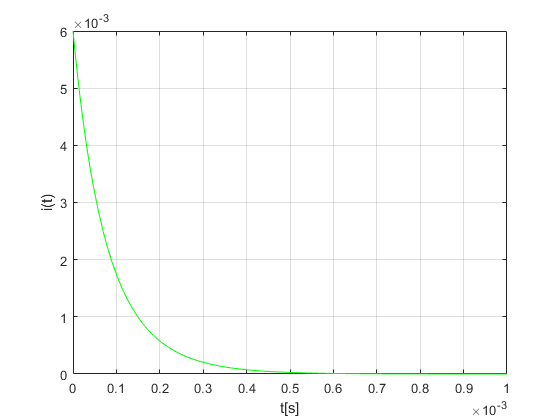

figure ()
fplot(i(t),[0.0 0.001],'g' )
grid on
xlabel('t[s]')
ylabel('i(t)')

Circuit can be simulated  in MATLAB Simulink [./Simulink\Serial_RLC.slx](matlab:open('./Simulink\Serial_RLC.slx'))

            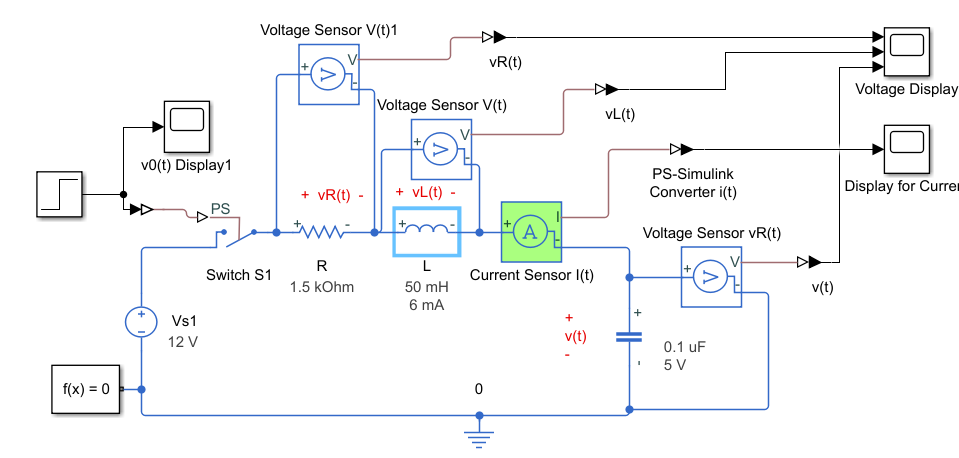

MATLAB simulation gives the following plots

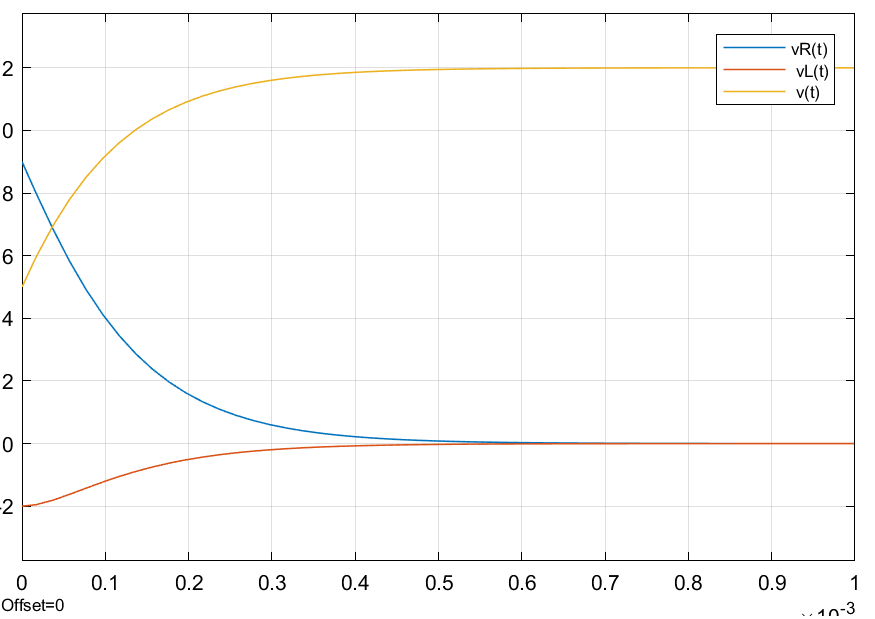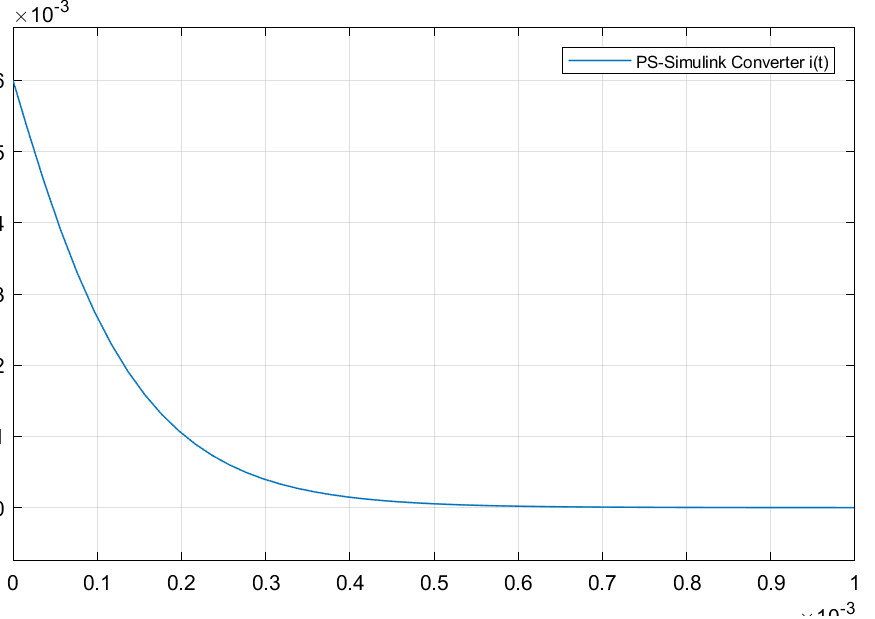

#### Example 1. Step Response of Serial RLC Circuit

In the following serial RLC circuit, no energy is stored in the $100 mH$ inductor or the $0.4\mu F$capacitor when the switch in the circuit is closed at $t = 0$.

- Find and plot the voltage across the capacitor $v(t)$ for $t \ge 0$

- Find and plot the current through the circuit  $i(t)$ for $t \ge 0$

- Find and plot the voltage across the inductor $v_L(t)$ for $t \ge 0$

- Find and plot the voltage across the resistor $R_1$ $v_{R1}(t)$ for $t \ge 0$

- Find and plot the voltage across the resistor $R_2$ $v_{R2}(t)$ for $t \ge 0$

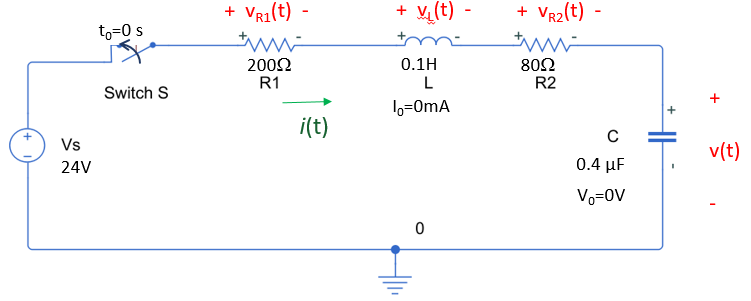

Given values in the circuit


R1 = 200       % Resistor_1 in ohms

R1 = 200

R2 = 80        % Resistor_2 in ohms

R2 = 80

L = 0.1          % Inductor in Henry

L = 0.1000

C = 0.4*10^-6  % Capacitor in Farad

C = 4.0000e-07

V0 = 0;        % Initial Voltage of Capacitor as Volts
I0 = 0;        % Initial Current of Inductor as Ampers
Vs = 24;         % DC Voltage source in Volts

Total resistance will be 

            
$$R=R_1+R_2$$


R = R1+R2;

R = 280

We can find  

            $a_1=\frac{R}{L},a_0=\frac{1}{LC}, $ and $b_0=\frac{V_s}{LC}$

a1 = R/L; a0 = 1/(L*C); b0 = Vs/(L*C);

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}v\left(t\right)+2800\,\frac{\partial }{\partial t}v\left(t\right)+25000000\,v\left(t\right)=600000000$$

Then, differential equation will be 

             
$$\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + a_1\frac { d v ( t ) } { d t } + a_0 v ( t ) = b_0$$


Initial values are given:

            
$$v ( 0 ) = V _ { 0 }$$
                                                                 

            
$$ \frac { d v ( 0 ) } { d t } = \frac { i ( 0 ) } { C } = \frac { I _ { 0 } } { C }$$
                                                     

Solve the differential equation in MATLAB

syms v(t) t i(t) vR1(t) vR1(t) vL(t)

$$Dv(t) = \frac{\partial }{\partial t}v\left(t\right)$$

eq = diff(v,t,2) + a1*diff(v,t)+a0*v ==  b0 

$$cond = \left(\begin{array}{cc} v\left(0\right)=0 & \left({\left(\frac{\partial }{\partial t}v\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

Dv = diff(v,t)

$$v(t) = 24-7\,\sin\left(4800\,t\right)\,{\mathrm{e}}^{-1400\,t}-24\,\cos\left(4800\,t\right)\,{\mathrm{e}}^{-1400\,t}$$

cond = [v(0) == V0, Dv(0)== I0/C]

$$v(t) = 24.0-7.0\,{\mathrm{e}}^{-1400.0\,t}\,\sin\left(4800.0\,t\right)-24.0\,{\mathrm{e}}^{-1400.0\,t}\,\cos\left(4800.0\,t\right)$$

v(t) = dsolve(eq, cond)
v(t) = vpa(v(t))

Ploting the voltage cross the capacitor  v(t)

fplot(v(t),[0.0 0.005],'r' )
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)')

The current through the capacitor is

            
$$i(t)=C \frac{dv(t)}{dt}$$


i(t) = C*diff(v(t))

$$i(t) = 0.05\,{\mathrm{e}}^{-1400.0\,t}\,\sin\left(4800.0\,t\right)$$

% i(t) = vpa(i(t),5)

The voltage across the resistor $R_1$is given by

            
$$v_{R1}(t)=R_1i(t)$$


vR1(t) = R1*i(t)

$$vR1(t) = 10.0\,{\mathrm{e}}^{-1400.0\,t}\,\sin\left(4800.0\,t\right)$$

Let's plot $v_{R1}(t)$ over v(t) in different color

hold on 
fplot(vR1(t),[0.0 0.005],'m' )

The voltage across the resistor $R_2$ is given by

            
$$v_{R2}(t)=R_2i(t)$$


vR2(t) = R2*i(t)

$$vR2(t) = 4.0\,{\mathrm{e}}^{-1400.0\,t}\,\sin\left(4800.0\,t\right)$$

Let's plot $v_{R2}(t)$ over v(t) in different color

hold on 
fplot(vR2(t),[0.0 0.005],'c' )

The voltage across the inductor is given by

          
$$v_L(t)=L \frac{di(t)}{dt}$$


vL(t) = L*diff(i(t))

$$vL(t) = 24.0\,{\mathrm{e}}^{-1400.0\,t}\,\cos\left(4800.0\,t\right)-7.0\,{\mathrm{e}}^{-1400.0\,t}\,\sin\left(4800.0\,t\right)$$

Let's plot $v_L(t)$ over v(t) with different color

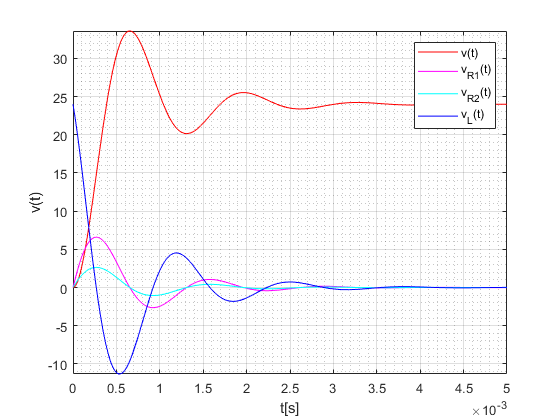

fplot(vL(t),[0.0 0.005],'b' )
legend ('v(t)', 'v_{R1}(t)', 'v_{R2}(t)','v_L(t)')

Ploting current $i(t)$ in seperate figure

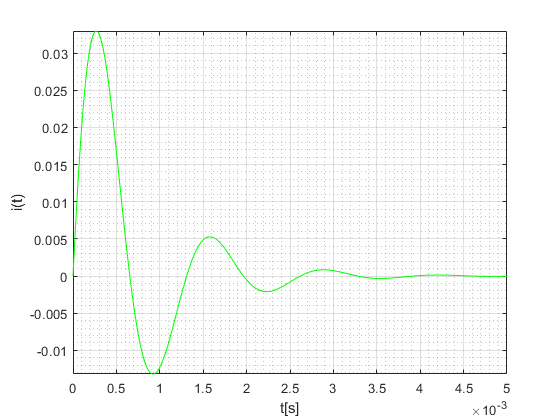

figure ()
fplot(i(t),[0.0 0.005],'g' )
grid on
grid minor
xlabel('t[s]')
ylabel('i(t)')

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

        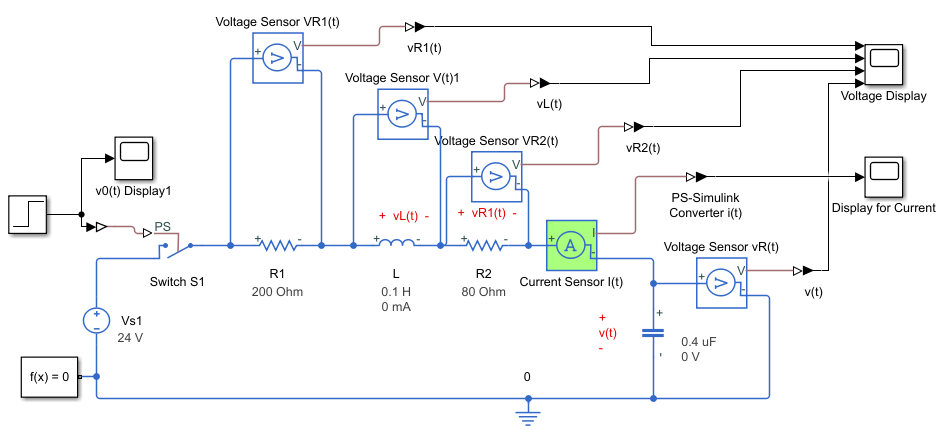

MATLAB simulation gives the following plots

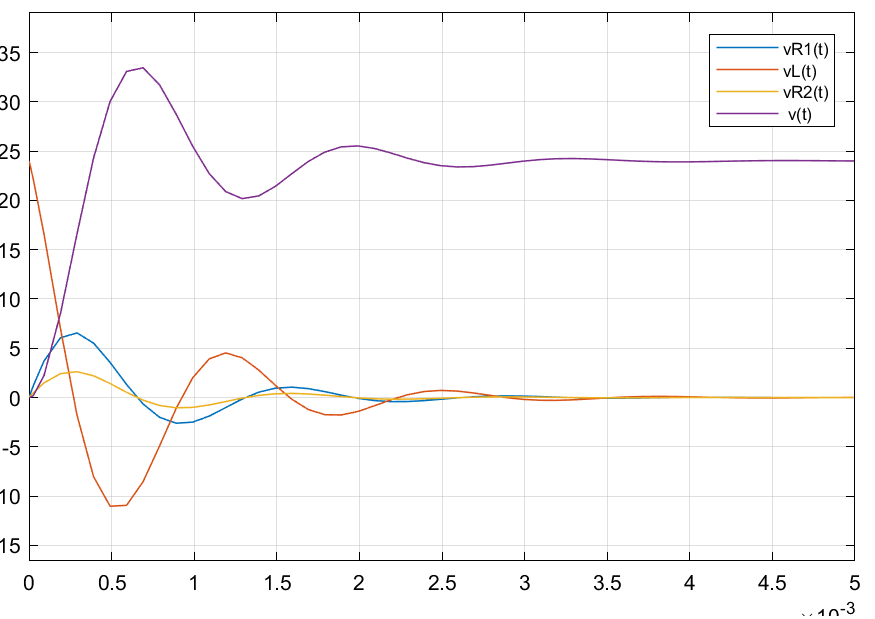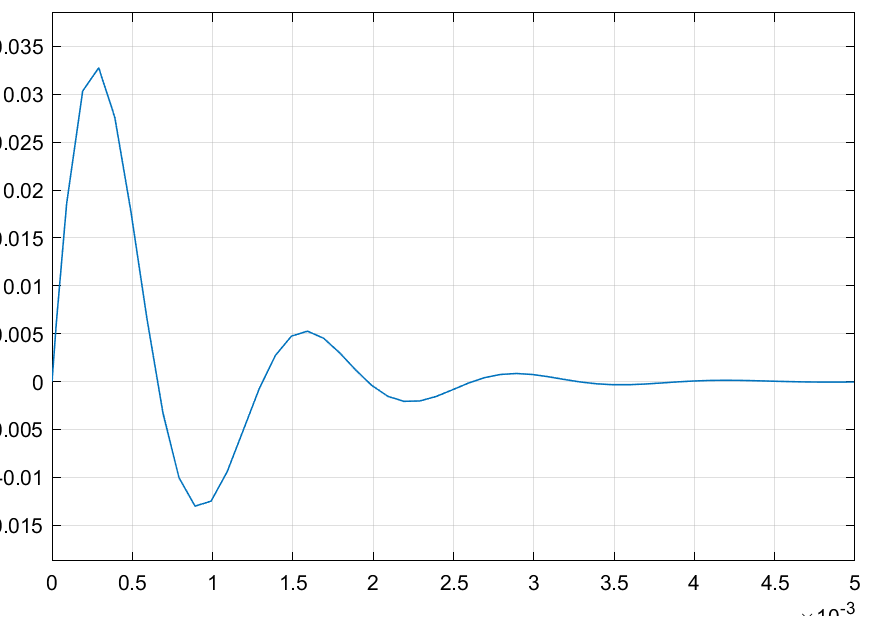

#### Exercise  1. Step Response of Serial RLC Circuit 

In the following  RLC circuit, $I_0=6mA$ is stored in the 100 mH inductor or $V_0=4V$is stored in the $0.4\mu F$capacitor when the switch in the circuit is closed at $t = 0$.

- Find and plot the voltage across the capacitor $v(t)$ for $t \ge 0$

- Find and plot the current through the circuit  $i(t)$ for $t \ge 0$

- Find and plot the voltage across the inductor $v_L(t)$ for $t \ge 0$

- Find and plot the voltage across the resistor $R_1$ $v_{R1}(t)$ for $t \ge 0$

- Find and plot the voltage across the resistor $R_2$ $v_{R2}(t)$ for $t \ge 0$

             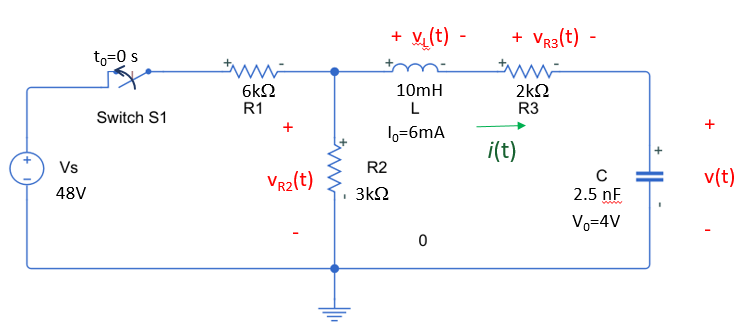           

   **Solution**

Given values in the circuit

% R1 = ?       % Resistor_1 kohms
% R2 = ?       % Resistor_2 kohms
% R3 = ?        % Resistor_3 kohms
% L = ?        % Inductor mH
% C = ?       % Capacitor uH
% V0 = ?;     % Initial Voltage of Capacitor
% I0 = ?;     % Initial Current of Inductor
% Vs = ?;     % DC Voltage source

In the circuit, use source transformatio for  $V_s$, $R_1$, to get $I_s$ 

% Is = ??

Find the equivalent resistance in the cuircuit using $R_1$ and $R_2$, 

% Ra = ??

Then, use source transformatio for  $I_s$, $R_a$, to bring in  serial  $V_s$ and$R_a$. 

Combine $R_a$ and $R_3$ in serial

% R = ??

 Next step is to find  $a_1, a_0, $ and $b_0$

%  a1 =?; a0 = ?; b0 = ?;

Differential equation will be 

 
$$\frac { d ^ { 2 } v ( t ) } { d t ^ { 2 } } + a_1\frac { d v ( t ) } { d t } + a_0 v ( t ) = b_0$$


Initial Values:

            
$$v ( 0 ) = V _ { 0 }$$
                                                                 

            
$$ \frac { d v ( 0 ) } { d t } = \frac { i ( 0 ) } { C } = \frac { I _ { 0 } } { C }$$
                                                     

Solve the differential equation in MATLAB

% syms v(t) t i(t) vR1(t) vR1(t) vL(t)
% eq = diff(v,t,2) + a1*diff(v,t)+a0*v ==  b0 
% Dv = diff(v,t)
% cond = [v(0) == V0, Dv(0)== I0/C]
% v(t) = dsolve(eq, cond)
% v(t)=vpa(v(t))
% 
% fplot(v(t),[0.0 0.0001],'r' )
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('v(t)')

Find the current through the capacitor

% i(t) = ?
% i(t)=vpa(i(t),5)

Find voltage across the resistor $R_3$

% vR3(t) = ?
% hold on 
% fplot(vR3(t),[0.0 0.0001],'m' )


Find the voltage across the inductor   

% vL(t) =?
% fplot(vL(t),[0.0 0.0001],'b' )


Find the voltage across the resistor $R_2$ is using $v_L(t), V_{R3}(t),$and $v(t)$ 

% vR2(t) = ?
% hold on 
% fplot(vR2(t),[0.0 0.0001],'c' )
% legend ('v(t)', 'v_{R1}(t)', 'v_{R2}(t)','v_L(t)')

Ploting current $i(t)$ in seperate figure

% figure ()
% fplot(i(t),[0.0 0.0001],'g' )
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('i(t)')


Simulate the circuit  in MATLAB Simulink 

        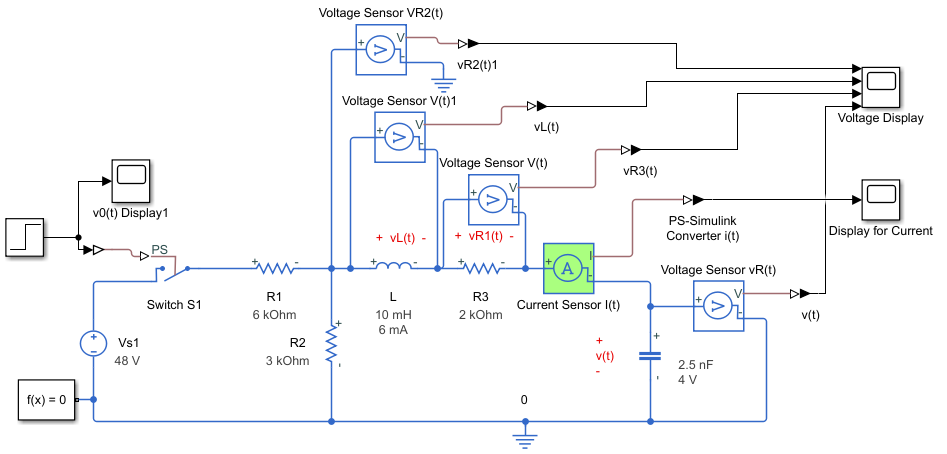

## Step Resposnes of Parallel RLC Circuit 

A parallel RLC circuit with constant independent current source is given in the following circuit

            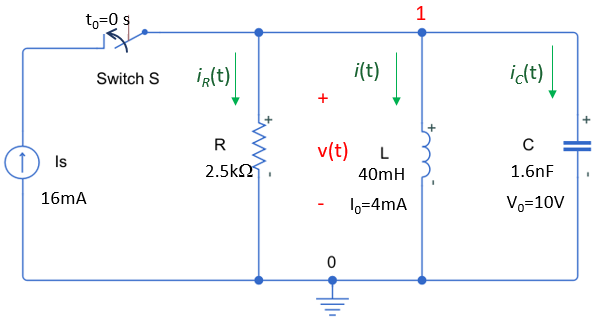

The switch in the circuit shown is closed at time $t=0$. Let the initial voltage across the capacitor at t = 0 be $V_0$, and the initial current through the inductor at t = 0 be $I_0$

  Sum the current  KCL at node 1

             
$$- I _ { s } + \frac{v(t)}{R} + i(t)+C \frac { dv ( t ) } { d t }  = 0$$
                           

 The voltage across the inductor is given by

            
$$v ( t ) = L \frac { d i ( t ) } { d t }$$
                                                     

 Substitute it  into previous equation

             
$$- I _ { s } + \frac{L}{R}\frac{di(t)}{dt} + i(t)+LC \frac { d^2i( t ) } { d t^2 }  = 0$$
 

Rearrange it and second order differential equation will be 

           
$$\frac { d ^ { 2 } i ( t ) } { d t ^ { 2 } } + \frac { 1 } { RC } \frac { d i ( t ) } { d t } + \frac { 1 } { L C } i ( t ) = \frac { 1 } { L C } I _ { s }$$


Given values in the circuit


R = 2.5e3;    %reisstor kohms
L =40e-3;     % Inductor mH
C = 1.6e-9;   % Capacitor uH

V0 = 10;        % Initial Voltage of Capacitor
I0 = 4e-3;      % Initial Current of Inductor
Is=16e-3;       % Current source 

 Let's have 

            $a_1=\frac{1}{RC},a_0=\frac{1}{LC}, $ and $b_0=\frac{I_s}{LC}$

a1 =1/(R*C); a0 = 1/(L*C); b0 = Is/(L*C);

Then, differential equation will be 

             
$$\frac { d ^ { 2 } i ( t ) } { d t ^ { 2 } } + a_1\frac { d i ( t ) } { d t } + a_0i ( t ) = b_0$$


Initial Values:

            
$$i ( 0 ) = I _0$$
                                                                 

            
$$ \frac { di( 0 ) } { d t } = \frac {V( 0 ) } { L } = \frac {V _ { 0 } } { L }$$
                                                     

In MATLAB

syms t i(t) v(t) iR(t) iC(t)
eq = diff(i,t,2) + a1*diff(i,t)+a0*i(t) ==  b0 

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}i\left(t\right)+250000\,\frac{\partial }{\partial t}i\left(t\right)+15625000000\,i\left(t\right)=250000000$$

Di=diff(i,t)

$$Di(t) = \frac{\partial }{\partial t}i\left(t\right)$$

cond = [i(0) == I0, Di(0)== V0/L]

$$cond = \left(\begin{array}{cc} i\left(0\right)=\frac{1}{250} & \left({\left(\frac{\partial }{\partial t}i\left(t\right)\right)|}_{t=0}\right)=250 \end{array}\right)$$

i(t) = dsolve(eq, cond)

$$i(t) = \frac{2}{125}-1250\,t\,{\mathrm{e}}^{-125000\,t}-\frac{3\,{\mathrm{e}}^{-125000\,t}}{250}$$

vpa(i(t),5)

$$ans = 0.016-1250.0\,t\,{\mathrm{e}}^{-125000.0\,t}-0.012\,{\mathrm{e}}^{-125000.0\,t}$$

Ploting the current $i(t) $through the inductor 

fplot(i(t),[0.0 0.0002],'g' )
grid on
grid minor
xlabel('t[s]')
ylabel('i(t)')


The voltage  across the inductor is given

            
$$v(t)=L \frac{di(t)}{dt}$$


v(t) = L*diff(i(t))

$$v(t) = 10\,{\mathrm{e}}^{-125000\,t}+6250000\,t\,{\mathrm{e}}^{-125000\,t}$$

v(t)=vpa(v(t))

$$v(t) = 10.0\,{\mathrm{e}}^{-1.25e+5\,t}+6.25e+6\,t\,{\mathrm{e}}^{-1.25e+5\,t}$$

The current through the resistor is

            
$$i_R(t)=\frac{v(t)}{R}$$


iR(t) = v(t)/R

$$iR(t) = 0.004\,{\mathrm{e}}^{-1.25e+5\,t}+2500.0\,t\,{\mathrm{e}}^{-1.25e+5\,t}$$

hold on 
fplot(iR(t),[0.0 0.0002],'m' )

The current through the capacitor is

            
$$i_C(t)=C \frac{dv(t)}{dt}$$


iC(t) = C*diff(v(t))

$$iC(t) = 0.008\,{\mathrm{e}}^{-1.25e+5\,t}-1250.0\,t\,{\mathrm{e}}^{-1.25e+5\,t}$$

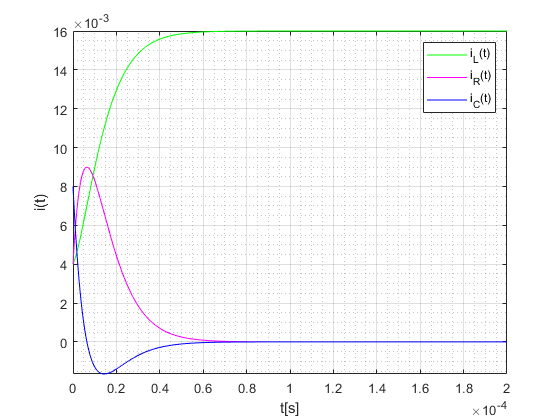

fplot(iC(t),[0.0 0.0002],'b' )
legend ('i_L(t)', 'i_R(t)', 'i_C(t)')

Ploting voltage $v(t)$

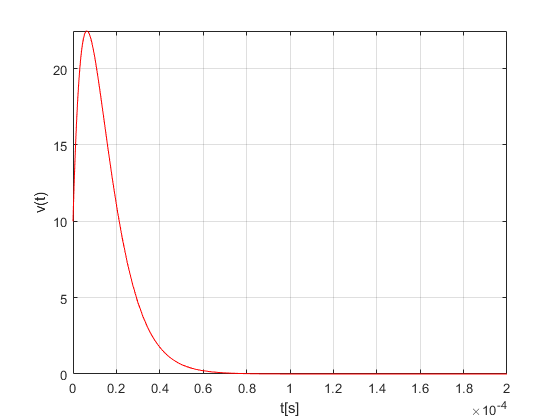

figure ()
fplot(v(t),[0.0 0.0002],'r' )
grid on
xlabel('t[s]')
ylabel('v(t)')

Circuit can be simulated  in MATLAB Simulink: [./Simulink\Parallel_RLC.slx](matlab:open('./Simulink\Parallel_RLC.slx'))

        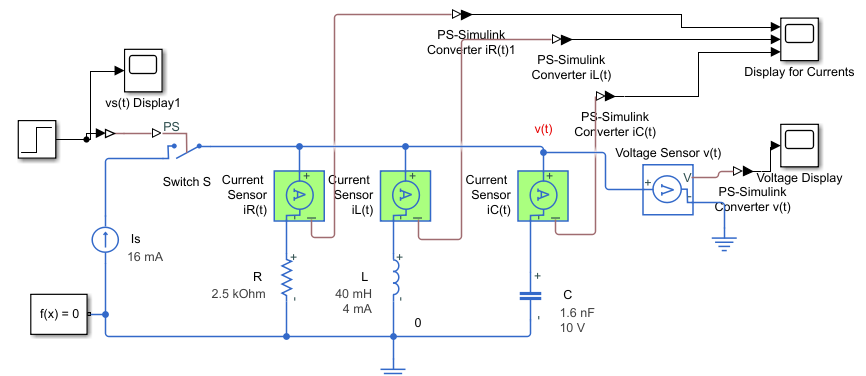

#### Example 2. Step Resposnes of Parallel RLC Circuit 

In the following  RLC circuit,  40mA energy is stored in the 40 mH inductor and 5Venergy is stored in  the 50 nF capacitor when the switch in the circuit is closed at $t \ge 0$.

- Find and plot the current through inductor  $i(t)$ for $t \ge 0$

- Find and plot the voltage  across the inductor  $v(t)$ for $t \ge 0$

- Find and plot the current through the resistor $R_2$ $i_R(t)$ for $t \ge 0$

- Find and plotthe current throug the capacitor  $i_C(t)$ for $t \ge 0$

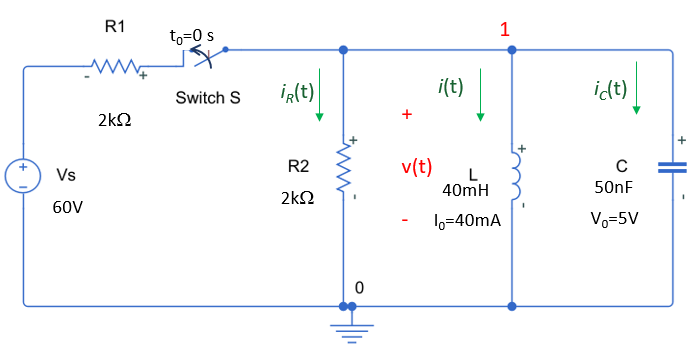

Given values in the circuit


R1 = 2e3;       % Resistor_1 ohms
R2 = 2e3        % Resistor_2 ohms

R2 = 2000

L = 40e-3       % Inductor H

L = 0.0400

C = 50e-9       % Capacitor uH

C = 5.0000e-08

V0 = 5;         % Initial Voltage of Capacitor
I0 = 40e-3;     % Initial Current of Inductor
Vs=60;          % DC Voltage source

$V_s$, $R_1$ can be simplfy using source transformation

        
$$I_s=\frac{V_s}{R_1}$$


Is = Vs/R1

Is = 0.0300

Then. $R_1 $will be parallel to $R_2$ and the equivalent resistance in the cuircuit 

        
$$R=\frac{R_1R_2}{R_1+R_2}$$


R = (R1*R2)/(R1+R2)

R = 1000

Let's have 

        $a_1=\frac{1}{RC},a_0=\frac{1}{LC}, $ and $b_0=\frac{I_s}{LC}$

a1 =1/(R*C); a0 = 1/(L*C); b0 = Is/(L*C);

Then, differential equation will be 

         
$$\frac { d ^ { 2 } i ( t ) } { d t ^ { 2 } } + a_1\frac { d i ( t ) } { d t } + a_0i ( t ) = b_0$$


Initial Values:

            
$$i ( 0 ) = I _0$$
                                                                 

            
$$ \frac { di( 0 ) } { d t } = \frac {V( 0 ) } { L } = \frac {V _ { 0 } } { L }$$
                                                     

In MATLAB

syms t i(t) v(t) iR(t) iC(t)
eq = diff(i,t,2) + a1*diff(i,t)+a0*i(t) ==  b0 

$$eq(t) = \frac{\partial^{2}}{\partial t^{2}}i\left(t\right)+20000\,\frac{\partial }{\partial t}i\left(t\right)+\frac{8388607999999999\,i\left(t\right)}{16777216}=\frac{8053063679999999}{536870912}$$

Di=diff(i,t)

$$Di(t) = \frac{\partial }{\partial t}i\left(t\right)$$

cond = [i(0) == I0, Di(0)== V0/L]

$$cond = \left(\begin{array}{cc} i\left(0\right)=\frac{1}{25} & \left({\left(\frac{\partial }{\partial t}i\left(t\right)\right)|}_{t=0}\right)=125 \end{array}\right)$$

i(t) = dsolve(eq, cond);
i(t) = vpa(i(t),6)

$$i(t) = 0.01\,{\mathrm{e}}^{-10000.0\,t}\,\cos\left(20000.0\,t\right)+0.01125\,{\mathrm{e}}^{-10000.0\,t}\,\sin\left(20000.0\,t\right)+0.03$$

Ploting the current $i(t) $through the inductor 

fplot(i(t),[0.0 0.001],'g' )
grid on
grid minor
xlabel('t[s]')
ylabel('i(t)')


The voltage  across the inductor is

            
$$v(t)=L \frac{di(t)}{dt}$$


v(t) = L*diff(i(t))

$$v(t) = 5.0\,{\mathrm{e}}^{-10000.0\,t}\,\cos\left(20000.0\,t\right)-12.5\,{\mathrm{e}}^{-10000.0\,t}\,\sin\left(20000.0\,t\right)$$

v(t) = vpa(v(t),6)

$$v(t) = 5.0\,{\mathrm{e}}^{-10000.0\,t}\,\cos\left(20000.0\,t\right)-12.5\,{\mathrm{e}}^{-10000.0\,t}\,\sin\left(20000.0\,t\right)$$

The current through the resistor is

            
$$i_R(t)=\frac{v(t)}{R}$$


iR(t) = v(t)/R

$$iR(t) = 0.005\,{\mathrm{e}}^{-10000.0\,t}\,\cos\left(20000.0\,t\right)-0.0125\,{\mathrm{e}}^{-10000.0\,t}\,\sin\left(20000.0\,t\right)$$

hold on 
fplot(iR(t),[0.0 0.001],'m' )

The current through the capacitor is

            
$$i_C(t)=C \frac{dv(t)}{dt}$$


iC(t) = C*diff(v(t))

$$iC(t) = 0.00125\,{\mathrm{e}}^{-10000.0\,t}\,\sin\left(20000.0\,t\right)-0.015\,{\mathrm{e}}^{-10000.0\,t}\,\cos\left(20000.0\,t\right)$$

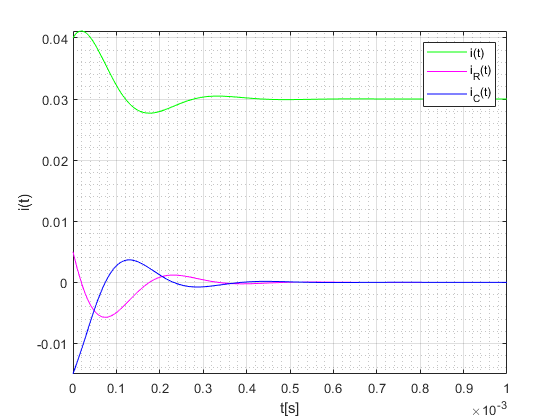

fplot(iC(t),[0.0 0.001],'b' )
legend ('i(t)', 'i_R(t)', 'i_C(t)')

Ploting voltage $v(t)$

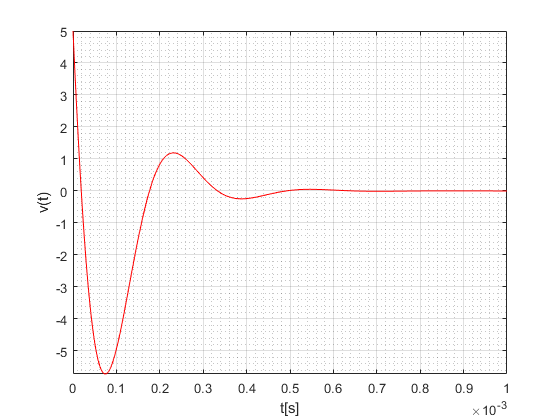

figure ()
fplot(v(t),[0.0 0.001],'r' )
grid on
grid minor
xlabel('t[s]')
ylabel('v(t)')

Circuit can be simulated  in MATLAB Simulink  [./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

        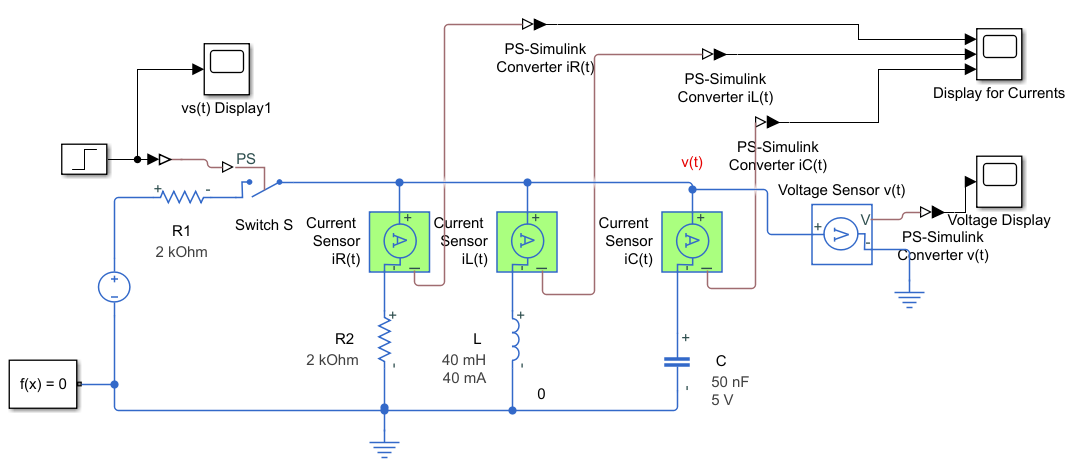

MATLAB simulation gives the following plots

#### Exercise  2.Step Resposnes of Parallel RLC Circuit 

In the following  RLC circuit,  no energy is stored in the 50 nH inductor and 5V energy is stored in  the $0.4\mu F$capacitor when the switch in the circuit is closed at $t \ge 0$.

- Find and plot the current through inductor  $i(t)$ for $t \ge 0$

- Find and plot the voltage  across the inductor  $v(t)$ for $t \ge 0$

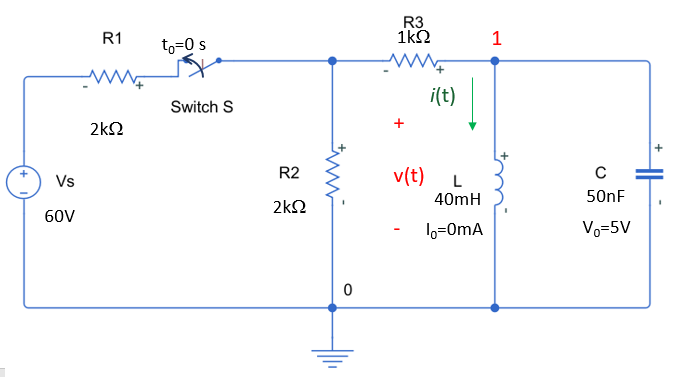

Given values in the circuit


% R1 = ? ;       % Resistor_1 kohms
% R2 = ? ;         % Resistor_2 kohms
% L = ? ;          % Inductor mH
% C = ? ;         % Capacitor nF
% V0 = ? ;        % Initial Voltage of Capacitor
% I0 = ? ;        % Initial Current of Inductor mA
% Vs = ?;         % DC Voltage source

Simplfy $V_s$, $R_1$  using source transformation

% Is = ?

Then, $R_1 $ will be parallel to $R_2$ and find the equivalent resistanceas $R_a$

% Ra = ?

Have another source transformation to find a voltage sourcee and serial resistor $R_a$

% Vs = ?

This time,  $R_a$ will be serial to $R_3$ and find  equivalent resistance as $R$

% R = ?

Have another source transformation to find current source $I_s$ and parallel resistor $R$

% Is = ?

Now you can find   $a_1,a_0$ and $b_0$

% a1 =?; a0 = ?; b0 =?;

Then, differential equation is 

             
$$\frac { d ^ { 2 } i ( t ) } { d t ^ { 2 } } + a_1\frac { d i ( t ) } { d t } + a_0i ( t ) = b_0$$


Initial Values are

            
$$i ( 0 ) = I _0$$
                                                                 

            
$$ \frac { di( 0 ) } { d t } = \frac {V( 0 ) } { L } = \frac {V _ { 0 } } { L }$$
                                                     

In MATLAB

% syms t i(t) v(t) iR(t) iC(t)
% eq = diff(i,t,2) + a1*diff(i,t)+a0*i(t) ==  b0 
% Di=diff(i,t)
% cond = [i(0) == I0, Di(0)== V0/L]
% i(t) = dsolve(eq, cond)
% i(t)=simplify(i(t))

Ploting the current $i(t) $through the inductor 

% fplot(i(t),[0.0 0.001],'g' )
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('i(t)')


Find the voltage  across the inductor

% v(t) = ?
% v(t)=vpa(v(t),10)

Find the current through the capacitor

% iC(t) = ?
% fplot(iC(t),[0.0 0.001],'b' )
% legend ('i(t)',  'i_C(t)')

Ploting voltage $v(t)$

% figure ()
% fplot(v(t),[0.0 0.001],'r' )
% grid on
% grid minor
% xlabel('t[s]')
% ylabel('v(t)')


  Simulate  this exercise using MATLAB Simulink to check your values. 

### 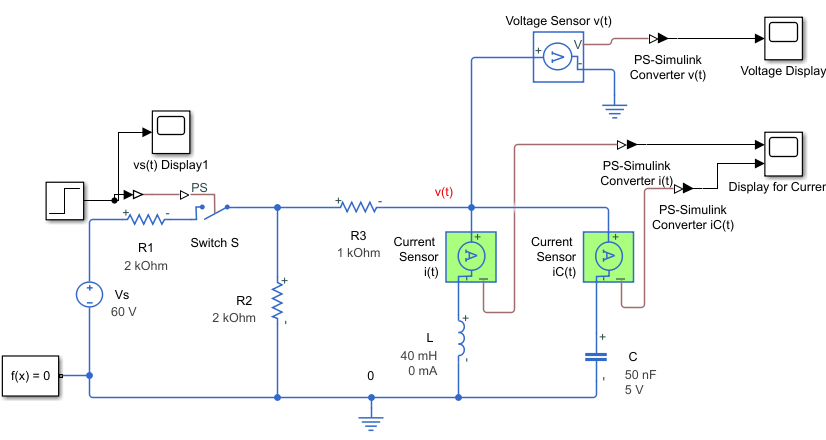

### References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018